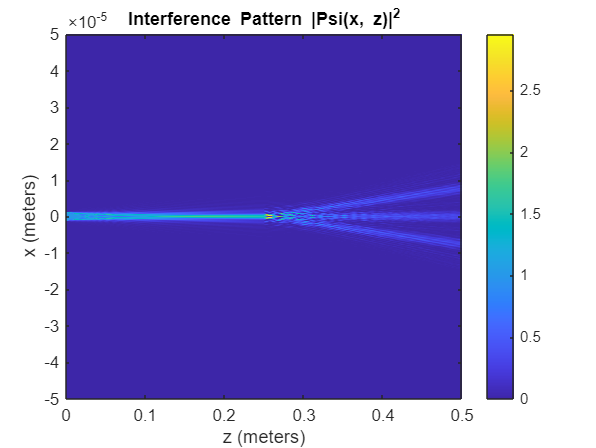

%  V


clear; clc; close all;


lambda_dB = 0.12e-10;  
v_most_probable = 850;  
vel_spread = 0.6 * v_most_probable;  
k0 = 2 * pi / lambda_dB;  


grating_period = 405e-9;   
grating_separation = 0.25; 
total_length = 0.5;        
source_slit_width = 2.5e-6;   


x_range = [-50e-6, 50e-6];  
z_range = [0, total_length]; 
n_x = 1000;  
n_z = 1000;  

x = linspace(x_range(1), x_range(2), n_x);  
z = linspace(z_range(1), z_range(2), n_z);  
[X, Z] = meshgrid(x, z);  


beam_divergence_angle = 32e-6; 
beam_velocity_spread = vel_spread / v_most_probable;  
deBroglie_wavelength = lambda_dB;  


Psi0 = double(abs(x) < source_slit_width / 2);  


function Psi_out = fresnel_propagation(Psi_in, dz, lambda, x, k0)
    % Input: Psi_in (wavefunction), dz (propagation distance),
    % lambda (de Broglie wavelength), x (transverse positions),
    % k0 (wave number corresponding to the de Broglie wavelength)
    
    dx = x(2) - x(1);  
    kx = linspace(-pi/dx, pi/dx, length(x));  
    
    Psi_fft = fftshift(fft(Psi_in));
   
    H = exp(-1i * dz * kx.^2 / (2 * k0));
    
    Psi_out = ifft(ifftshift(Psi_fft .* H));
end


function Psi_out = phase_grating(Psi_in, phase_shift, grating_period, x)
    % Input: Psi_in (wavefunction), phase_shift (applied phase), 
    % grating_period (period of grating), x (transverse position)
    % Output: Psi_out (after passing through grating)
    
    Psi_out = Psi_in .* exp(1i * phase_shift * cos(2 * pi * x / grating_period));
end


phase_shift_1 = pi / 2;  
phase_shift_2 = pi;      
phase_shift_3 = pi / 2;  


Psi = zeros(n_z, n_x);  
Psi(1,:) = Psi0;        


for i = 2:n_z
    dz = z(i) - z(i-1); 
    
    
    Psi(i,:) = fresnel_propagation(Psi(i-1,:), dz, lambda_dB, x, k0);
    
   
    if abs(z(i) - 0.25) < dz / 2  
        Psi(i,:) = phase_grating(Psi(i,:), phase_shift_2, grating_period, x);
    elseif abs(z(i) - 0.5) < dz / 2  
        Psi(i,:) = phase_grating(Psi(i,:), phase_shift_3, grating_period, x);
    elseif abs(z(i)) < dz / 2 
        Psi(i,:) = phase_grating(Psi(i,:), phase_shift_1, grating_period, x);
    end
end


figure;
imagesc(z, x, abs(Psi').^2);
colorbar;
xlabel('z (meters)');
ylabel('x (meters)');
title('Interference Pattern |Psi(x, z)|^2');
axis xy;  

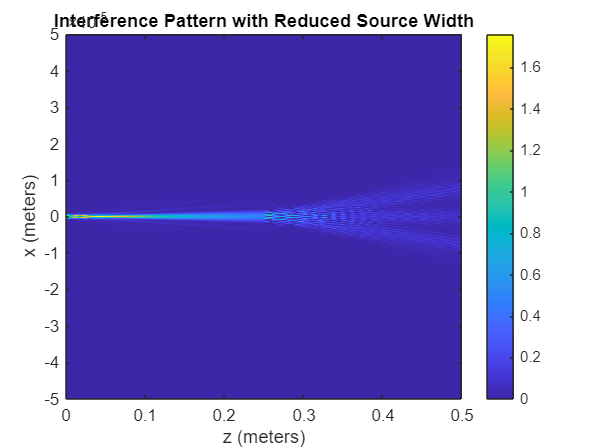



reduced_slit_width = source_slit_width / 2; 
Psi0_reduced = double(abs(x) < reduced_slit_width / 2);  

Psi_reduced = zeros(n_z, n_x);  
Psi_reduced(1,:) = Psi0_reduced;  


for i = 2:n_z
    dz = z(i) - z(i-1); 
    Psi_reduced(i,:) = fresnel_propagation(Psi_reduced(i-1,:), dz, lambda_dB, x, k0);
    
   
    if abs(z(i) - 0.25) < dz / 2  
        Psi_reduced(i,:) = phase_grating(Psi_reduced(i,:), phase_shift_2, grating_period, x);
    elseif abs(z(i) - 0.5) < dz / 2  
        Psi_reduced(i,:) = phase_grating(Psi_reduced(i,:), phase_shift_3, grating_period, x);
    elseif abs(z(i)) < dz / 2  
        Psi_reduced(i,:) = phase_grating(Psi_reduced(i,:), phase_shift_1, grating_period, x);
    end
end


figure;
imagesc(z, x, abs(Psi_reduced').^2);
colorbar;
% colormap('hot');
xlabel('z (meters)');
ylabel('x (meters)');
title('Interference Pattern with Reduced Source Width');
axis xy;

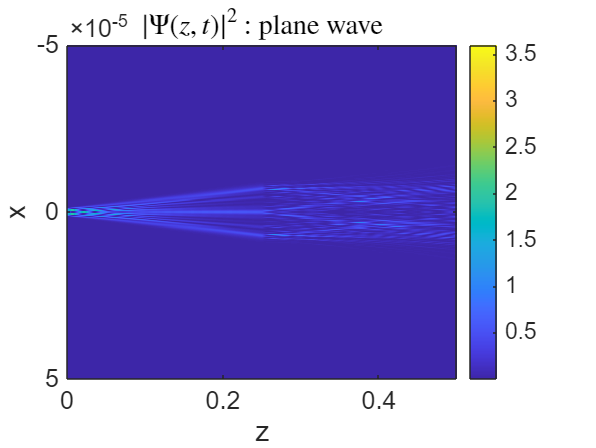

hbar = [1.044e-34,1]; 

N = 2^16;

xmax = 10e-3;       

dx = xmax/N;

n = 0:1:(N-1); p = n;

xn = -xmax/2 + n*dx;

pmax = 2*pi*hbar(1)/dx;

dp = 2*pi*hbar(1)/xmax;

pn = -pmax/2 + p.*dp;

z_12 = 0.25;                    
z_23 = 0.25;                       
source_slit = 2.5e-6;             


detector_size = 100e-6;          
lam_dB = 0.12e-10;             
m_n = 1.675e-27;                
d = 8e-6;                     
diffract_slit = 1e-6;        
slit_separation = 8e-6;     
fill_factor = 50;
lam = 811e-9;               
k_vec = 2*pi/lam;           

m_Ar = 40*m_n;

Nz = 999;
zend1 = z_12;
zend2 = z_23;
dz = zend1/Nz;
z1 = 0:dz:zend1;
z2 = 0:dz:zend2;

v = 850;        

dt = dz/v;

% dU = exp(-1i*pn.^2.*dt./2./m_n./hbar(1));
U = dU(dt,pn,m_Ar,hbar(1));
phi01 = 2.56;
phi02 = 4.34;       
dphi1 = phi01.*(cos(k_vec.*xn)).^2;
dphi2 = phi02.*(cos(k_vec.*xn)).^2;


rect1 = @(x) double(abs(x) <= source_slit/2);  
source = rect1(xn);
phase_grating1 = exp(1i.*dphi1);
% figure;
% plot(xn,phase_grating1);
% xlim([-0.5e-4,0.5e-4]);
phase_grating2 = exp(1i.*dphi2);
% figure;
% plot(xn,phase_grating2);
% phi0*sin(4*pi*x/lam)
% xlim([-0.5e-4,0.5e-4]);


psi0_pw = source;      
% figure; 
% plot(xn,psi0_pw);
psi1_x = phase_grating1.*psi0_pw;  
% figure;
% plot(xn,psi1_x);
psi2_p = ftxtop(psi1_x,dx,hbar(1));   


Psi0_p1 = zeros(length(z1),length(psi2_p));
Psi0_x1 = zeros(length(z1),length(psi2_p));

for zi = 1:length(z1)
    dt = z1(zi)./v;
    Psi0_p1(zi,:) = dU(dt,pn,m_Ar,hbar(1)).*psi2_p;
    Psi0_x1(zi,:) = iftptox(Psi0_p1(zi,:),dp,hbar(1));
end

ap = (xn >= -detector_size/2 & xn <= detector_size/2);
x_limited = xn(ap);
% figure;
% % imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0_pw_x').^2);
% imagesc([0,z_12],[-detector_size/2, detector_size/2],abs(Psi0_x1(:,ap)').^2);
% set(gca,'FontSize',15);
% xlabel('z');
% ylabel('x');
% title('$|\Psi(z,t)|^2$ : plane wave',Interpreter='latex');
% colormap parula;
% colorbar;



psi0_2 = Psi0_x1(end,:);        
psi1_2 = phase_grating2.*psi0_2;       
psi1_2p = ftxtop(psi1_2,dx,hbar(1));


Psi1_p1 = zeros(length(z2),length(psi1_2p));
Psi1_x1 = zeros(length(z2),length(psi1_2p));

for zi = 1:length(z2)
    dt = z2(zi)./v;
    Psi1_p1(zi,:) = dU(dt,pn,m_Ar,hbar(1)).*psi1_2p;
    Psi1_x1(zi,:) = iftptox(Psi1_p1(zi,:),dp,hbar(1));
end

% figure;
% % imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0_pw_x').^2);
% imagesc([0,z_23],[-detector_size/2, detector_size/2],abs(Psi1_x1(:,ap)').^2);
% set(gca,'FontSize',15);
% xlabel('z');
% ylabel('x');
% title('$|\Psi(z,t)|^2$ : plane wave',Interpreter='latex');
% colormap parula;
% colorbar;

Psi = vertcat(Psi0_x1,Psi1_x1);
% ap = (xn >= -detector_size/2 & xn <= detector_size/2);
% x_limited = xn(ap);

figure;
imagesc([0,(z_12 + z_23)],[-detector_size/2, detector_size/2],abs(Psi(:,ap)').^2);
%[0,(z_12 + z_23)],
hold on;
%xline(z_12,'LineWidth',3);
set(gca,'FontSize',15);
xlabel('z');
ylabel('x');
title('$|\Psi(z,t)|^2$ : plane wave',Interpreter='latex');
colormap parula;
colorbar;

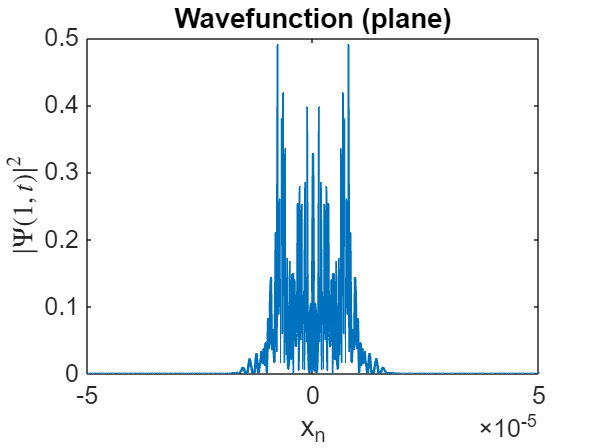


figure;
plot(xn,abs(Psi(end,:)).^2,'LineWidth',1.5);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title('Wavefunction (plane)');
set(gca,'FontSize',15);
xlim([-detector_size/2,detector_size/2]);






function [U] = dU(dt,p,m,hbar)
    U = exp(-1i.*(p.^2).*dt./2./m./hbar);
end

function [fp] = ftxtop(fx,dx,hbar)
    N  = length(fx);
    fp = dx*(1/2/pi/hbar)^(1/2)*fftshift(fft(ifftshift(fx)));
end

function [fx] = iftptox(fp,dp,hbar)
    N  = length(fp);
    fx = (N)*dp*(1/2/pi/hbar)^(1/2)*ifftshift(ifft(fftshift(fp)));
end